clear; close all; clc;

% Symbolic variables
t = sym('t', ["positive", "real"]);
n = sym('n', ["positive", "integer"]);

% Additional parameters
% L = sym('L', ["positive", "real"]); 
% L = 1;

% Original signal
f = piecewise( ...
    0 <= t & t < 1, 3 * t + 1, ...
    1 <= t & t < 2, 4 * exp(-5 * (t - 1)), ...
    0 ...
)

$$f = \left\{ \begin{array}{cl} 3\,t+1 & \text{ if }t<1\\ 4\,{\mathrm{e}}^{5-5\,t} & \text{ if }t\in \left[1,2\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$


% Signal period
t0 = 0;
T = 2;
T2 = 2 * T; % usually used in even and odd Fourier series

% Fourier series coefficients
aF0 = 1/T * int(f, t, t0, t0 + T);
aFn = 2/T * simplify(int(f .* cos(2 * pi * n / T * t), t, t0, t0 + T));
bFn = 2/T * simplify(int(f .* sin(2 * pi * n / T * t), t, t0, t0 + T));

% Complex Fourier series coefficients
c0 = aF0

$$c0 = \frac{33}{20}-\frac{2\,{\mathrm{e}}^{-5}}{5}$$

cn = 1/T * simplify(int(f .* exp(-2j * pi * n / T * t), t0, t0 + T))

$$cn = \frac{{\mathrm{e}}^{-5}\,\left(23\,\pi \,{\left(-1\right)}^{n}\,n\,{\mathrm{e}}^{5}-8\,\pi \,n\,{\mathrm{e}}^{5}+15\,{\mathrm{e}}^{5}\,\mathrm{i}-15\,{\left(-1\right)}^{n}\,{\mathrm{e}}^{5}\,\mathrm{i}+4\,n^{2}\,\pi^{2}\,\mathrm{i}-n^{2}\,\pi^{2}\,{\mathrm{e}}^{5}\,\mathrm{i}\right)}{2\,n^{2}\,\pi^{2}\,\left(\pi \,n-5\,\mathrm{i}\right)}$$


% Even Fourier series coefficients
aC0 = 2/T2 * int(f, t, t0, t0 + T2/2);
aCn = 4/T2 * simplify(int(f .* cos(2 * pi * n / T2 * t), t, t0, t0 + T2/2));

% Odd Fourier series coefficients
bSn = 4/T2 * simplify(int(f .* sin(2 * pi * n / T2 * t), t, t0, t0 + T2/2));

% Number of harmonics
N = 15;

% Fourier series
fF = aF0 + symsum(aFn * cos(2 * pi * n / T * t) + bFn * sin(2 * pi * n / T * t), n, 1, N);
% Complex Fourier series
fc = c0 + symsum(cn * exp(2j * pi * n / T * t), n, 1, N) + symsum(cn * exp(2j * pi * n / T * t), n, -N, -1);
% Even Fourier series
fC = aC0 + symsum(aCn * cos(2 * pi * n / T2 * t), n, 1, N);
% Odd Fourier series
fS = symsum(bSn * sin(2 * pi * n / T2 * t), n, 1, N);

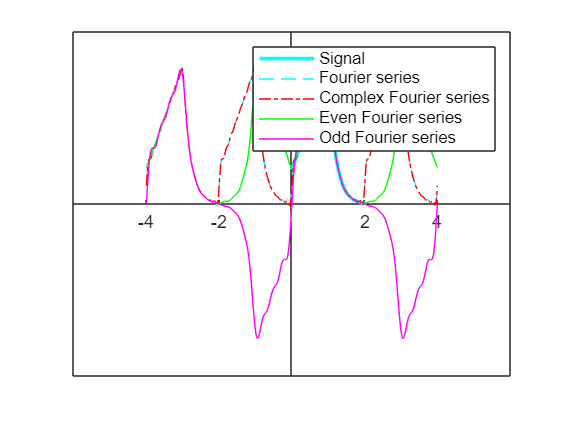

figure
ax = axes;

handle = fplot(f, [0 T], Color='cyan', LineWidth=2); handle.ShowPoles = 'off';
hold on
handle = fplot(fF, [-2 * T 2 * T], '--', Color='cyan'); handle.ShowPoles = 'off';
handle = fplot(fc, [-2 * T 2 * T], '-.', Color='red'); handle.ShowPoles = 'off';
handle = fplot(fC, [-2 * T 2 * T], Color='green'); handle.ShowPoles = 'off';
handle = fplot(fS, [-2 * T 2 * T], Color='magenta'); handle.ShowPoles = 'off';

ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
xlim([-3 * T 3 * T])
ylim([-5 5])
legend(["Signal", "Fourier series", "Complex Fourier series", "Even Fourier series", "Odd Fourier series"])